# Simscape multibody model og Regbot in balance

initial setup with motor velocity controller this is intended as simulation base for balance control.

close all
clear

## Simulink model name

model='regbot_1mg';

## parameters for REGBOT

motor

RA = 3.3/2;    % ohm (2 motors)
JA = 1.3e-6*2; % motor inertia
LA = 6.6e-3/2; % rotor inductor (2 motors)
BA = 3e-6*2;   % rotor friction
Kemf = 0.0105; % motor constant
Km = Kemf;
% køretøj
NG = 9.69; % gear
WR = 0.03; % wheel radius
Bw = 0.155; % wheel distance
%
% model parts used in Simulink
mmotor = 0.193;   % total mass of motor and gear [kg]
mframe = 0.32;    % total mass of frame and base print [kg]
mtopextra = 0.97 - mframe - mmotor; % extra mass on top (charger and battery) [kg]
mpdist =  0.10;   % distance to lit [m]
% disturbance position (Z)
pushDist = 0.1; % relative to motor axle [m]

## Own REGBOT parameters

RA = 6.4/2;    % ohm (2 motors)
JA = 1.3e-6*2; % motor inertia
LA = 6.6e-3/2; % rotor inductor (2 motors)
BA = 3e-6*2;   % rotor friction
Kemf = 0.008; % motor constant
Km = Kemf;
% køretøj
NG = 9.69; % gear
WR = 0.03; % wheel radius
Bw = 0.155; % wheel distance
%
% model parts used in Simulink
mmotor = 0.193;   % total mass of motor and gear [kg]
mframe = 0.32;    % total mass of frame and base print [kg]
mtopextra = 0.97 - mframe - mmotor; % extra mass on top (charger and battery) [kg]
mpdist =  0.10;   % distance to lit [m]
% disturbance position (Z)
pushDist = 0.1; % relative to motor axle [m]

## wheel velocity controller (no balance) PI-regulator

sample (usable) controller values

Kpwv = 15;     % Kp
tiwv = 0.05;   % Tau_i
Kffwv = 0;     % feed forward constant
startAngle = 10;  % tilt in degrees at time zero
twvlp = 0.005;    % velocity noise low pass filter time constant (recommended)
K_post = 1;
t_post = 1;
t_lead_tw = 0;
t_i_tw = 1;
K_tw = 1;
s = tf('s');

## Estimate transfer function for base system using LINEARIZE

Motor volatge to wheel velocity (wv)

load_system(model);
open_system(model);
% define points in model
ios(1) = linio(strcat(model,'/Limit9v'),1,'openinput');
ios(2) = linio(strcat(model, '/wheel_vel_filter'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
Gwv = minreal(tf(num, den))

Gwv =
 
                  5.351e05 s^3 + 5.351e08 s^2 - 3.873e07 s - 3.873e10
  -----------------------------------------------------------------------------------
  s^6 + 2888 s^5 + 2.213e06 s^4 + 3.435e08 s^3 + 1.417e09 s^2 - 5.737e10 s - 1.306e11
 
Continuous-time transfer function.
Model Properties


## Transfer function from previous exercise

Gwv = tf(2.183,[1 6.651]);

## Bodeplot

pole(Gwv)

ans = -6.6510

isstable(Gwv)

ans = logical
   1


h = figure(100)

h =   Figure (100) with properties:

      Number: 100
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


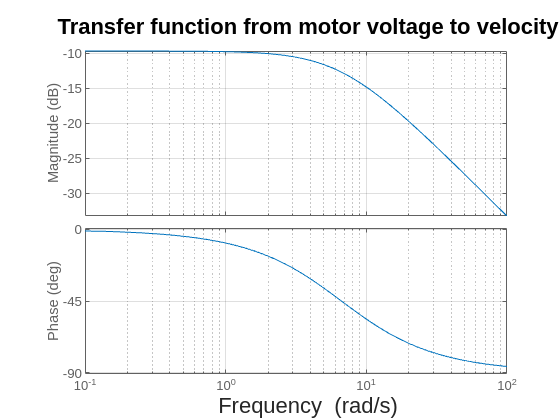

bode(Gwv)
grid on
title('Transfer function from motor voltage to velocity')

% saveas(h, 'motor to velocity.png');

## PI-Controller for voltage to velocity

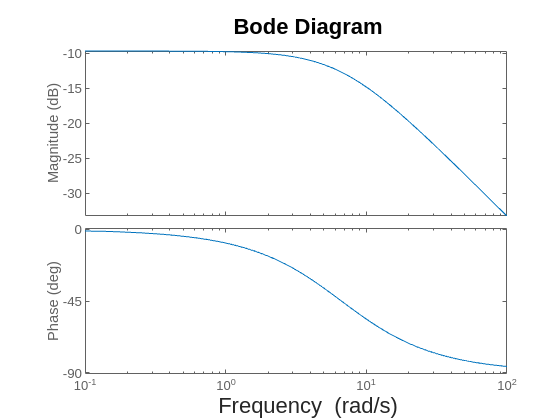

%Design parameters
N_i = 3;
gamma_m = 90;

phi_i = rad2deg(-atan(1/N_i));
phi_G = -180+gamma_m-phi_i;

bode(Gwv)

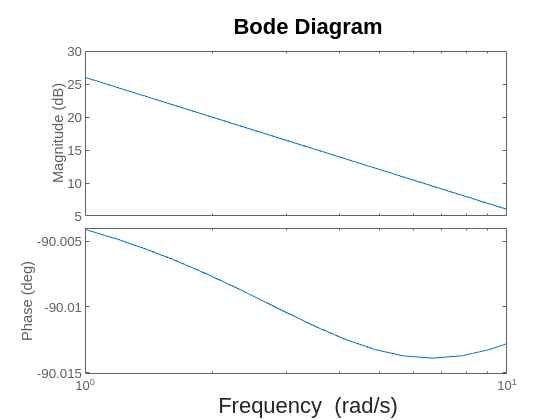


[mag,phase,wout] = bode(Gwv);
omega_c = interp1(squeeze(phase),wout,phi_G);
tau_i = N_i/omega_c;
C_i = tf([tau_i 1],[tau_i 0]);
Kp = 1/abs(freqresp(C_i*Gwv,omega_c*1i));
G_ol = Kp*C_i*Gwv;
G_wv_cl = G_ol/(1+G_ol);
bode(G_ol)

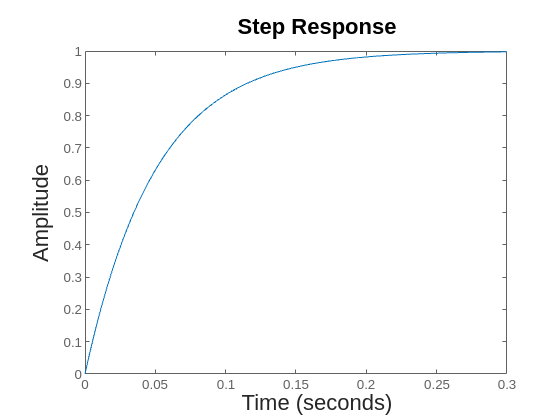

step(G_wv_cl)

## Flush values to model

Kpwv = Kp

Kpwv = 9.1442

tiwv = tau_i

tiwv = 0.1503

## **Transfer function from velocity to tilt using linearize**

% define points in model
ios(1) = linio(strcat(model,'/vel_ref'),1,'openinput');
ios(2) = linio(strcat(model, '/tilt_angle'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
Gtw = minreal(tf(num, den))

Gtw =
 
                 -2.737e05 s^4 - 3.544e08 s^3 - 6.192e10 s^2 - 3.966e11 s - 1.187e09
  --------------------------------------------------------------------------------------------------
  s^7 + 2888 s^6 + 2.213e06 s^5 + 3.484e08 s^4 + 6.343e09 s^3 - 2.517e10 s^2 - 4.871e11 s - 2.357e12
 
Continuous-time transfer function.


h = figure(100)

h =   Figure (100) with properties:

      Number: 100
        Name: ''
       Color: [1 1 1]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


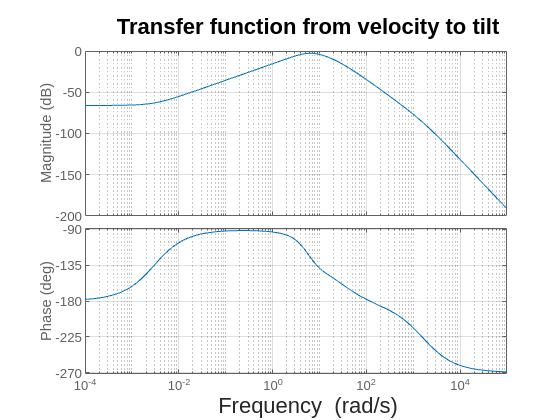

bode(-Gtw)
grid on
title('Transfer function from velocity to tilt')

[mag,phase,wout]=bode(Gtw);

## Post-Integrator

[gpeak,fpeak] = getPeakGain(-Gtw)

gpeak = 0.7318

fpeak = 6.3144

tau_i = 1/fpeak

tau_i = 0.1584

C_pi = -(tau_i*s+1)/(tau_i*s)

C_pi =
 
  -0.1584 s - 1
  -------------
    0.1584 s
 
Continuous-time transfer function.
Model Properties


G_post=Gtw*C_pi

G_post =
 
                4.334e04 s^5 + 5.641e07 s^4 + 1.016e10 s^3 + 1.247e11 s^2 + 3.968e11 s + 1.187e09
  --------------------------------------------------------------------------------------------------------------
  0.1584 s^8 + 457.4 s^7 + 3.504e05 s^6 + 5.518e07 s^5 + 1.004e09 s^4 - 3.986e09 s^3 - 7.714e10 s^2 - 3.732e11 s
 
Continuous-time transfer function.


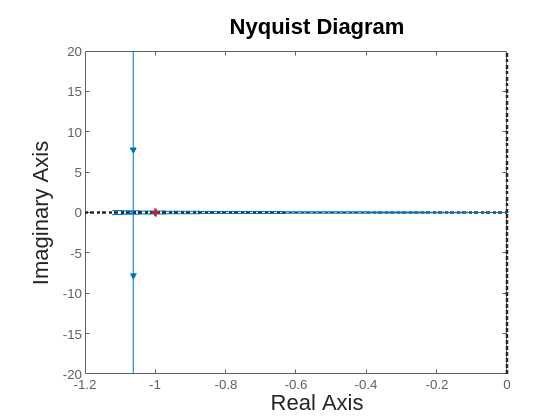

nyquist(G_post)

G_post_cl=minreal(G_post/(1+G_post))

G_post_cl =
 
                  2.737e05 s^5 + 3.562e08 s^4 + 6.416e10 s^3 + 7.876e11 s^2 + 2.506e12 s + 7.497e09
  -----------------------------------------------------------------------------------------------------------------
  s^8 + 2888 s^7 + 2.213e06 s^6 + 3.487e08 s^5 + 6.699e09 s^4 + 3.899e10 s^3 + 3.006e11 s^2 + 1.491e11 s + 7.497e09
 
Continuous-time transfer function.


isstable(G_post_cl)

ans = logical
   1


## Flush values to Simulink

K_post = -1

K_post = -1

t_post=tau_i

t_post = 0.1584

## Tilt controller PI-lead without filter

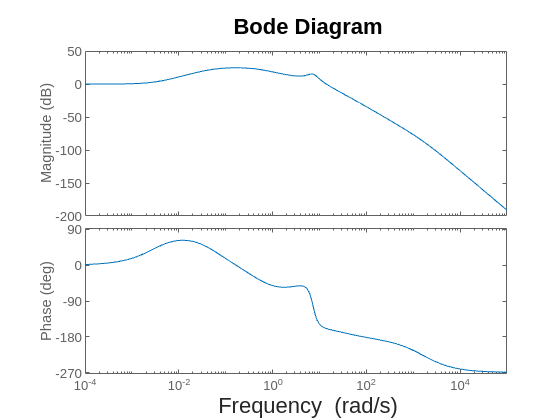

bode(G_post_cl)

% Design parameters
N_i = 3;
gamma_m = 60;
alpha = 0.0001;


phi_i = rad2deg(-atan(1/N_i));
phi_m = rad2deg(asin((1-alpha)/(1+alpha)));

phi_G = gamma_m - phi_i - phi_m - 180;
[mag,phase,wout] = bode(G_post_cl);
omega_c = interp1(squeeze(phase),wout,phi_G);

tau_D = 1/(omega_c*sqrt(alpha));
tau_i = N_i/omega_c;

C_i = tf([tau_i 1],[tau_i 0])

C_i =
 
  0.01213 s + 1
  -------------
    0.01213 s
 
Continuous-time transfer function.
Model Properties


C_D = tf([tau_D 1], [tau_D*alpha 1])

C_D =
 
   0.4043 s + 1
  ---------------
  4.043e-05 s + 1
 
Continuous-time transfer function.
Model Properties


[mag,phase] = bode((C_i*C_D*G_post_cl),omega_c);
Kp = 1/mag;

G_tw_ol = minreal(Kp*C_i*C_D*G_post_cl)

G_tw_ol =
 
               8.715e09 s^7 + 1.208e13 s^6 + 3.008e15 s^5 + 2.009e17 s^4 + 2.626e18 s^3 + 1.189e19 s^2 + 1.629e19 s + 4.868e16
  -----------------------------------------------------------------------------------------------------------------------------------------
  s^10 + 2.762e04 s^9 + 7.365e07 s^8 + 5.508e10 s^7 + 8.632e12 s^6 + 1.657e14 s^5 + 9.649e14 s^4 + 7.435e15 s^3 + 3.687e15 s^2 + 1.854e14 s
 
Continuous-time transfer function.


G_tw_cl = minreal(G_tw_ol/(1+G_tw_ol))

G_tw_cl =
 
                    8.715e09 s^7 + 1.208e13 s^6 + 3.008e15 s^5 + 2.009e17 s^4 + 2.626e18 s^3 + 1.189e19 s^2 + 1.629e19 s + 4.868e16
  ---------------------------------------------------------------------------------------------------------------------------------------------------
  s^10 + 2.762e04 s^9 + 7.365e07 s^8 + 6.38e10 s^7 + 2.071e13 s^6 + 3.174e15 s^5 + 2.019e17 s^4 + 2.634e18 s^3 + 1.189e19 s^2 + 1.629e19 s + 4.868e16
 
Continuous-time transfer function.


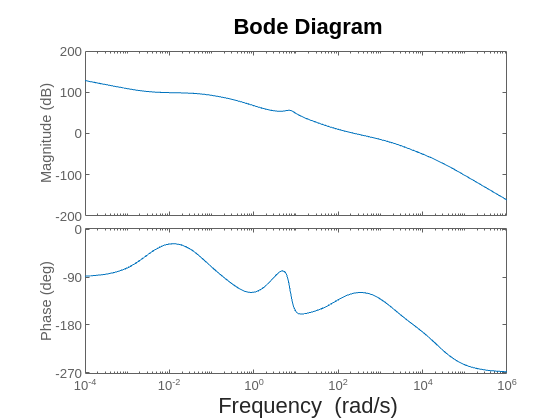


bode(G_tw_ol)

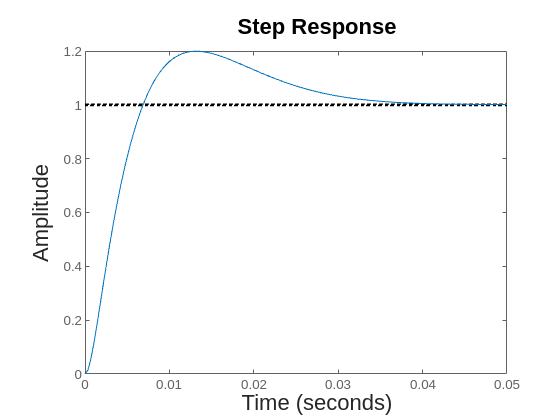

step(G_tw_cl)

## Flush values to simulink

t_lead_tw = tau_D;
t_i_tw = tau_i;
K_tw = 1%Kp;

K_tw = 1

## Transfer function from reference tilt to velocity using linearize

% define points in model
ios(1) = linio(strcat(model,'/tilt_ref'),1,'openinput');
ios(2) = linio(strcat(model, '/wheel_vel_filter'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
G_tref_w = minreal(tf(num, den))

G_tref_w =
 
                -4.893e06 s^6 - 4.971e09 s^5 - 7.766e10 s^4 - 3.015e10 s^3 + 5.051e12 s^2 + 2.822e13 s + 4.308e13
  ------------------------------------------------------------------------------------------------------------------------------
  s^9 + 2888 s^8 + 2.27e06 s^7 + 4.188e08 s^6 + 1.548e10 s^5 + 2.124e11 s^4 + 1.849e12 s^3 + 6.312e12 s^2 + 7.266e12 s + 2.17e10
 
Continuous-time transfer function.


## Reference tilt to velocity controller

isstable(G_tref_w)

ans = logical
   1


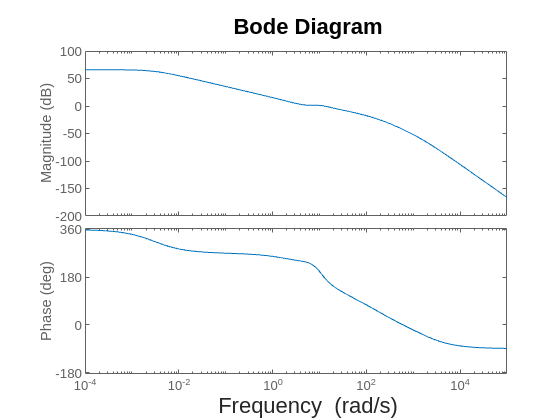

bode(G_tref_w)



% Design parameters
N_i = 10;
gamma_m = 120;
alpha = 0.3;


phi_i = rad2deg(-atan(1/N_i));
phi_m = rad2deg(asin((1-alpha)/(1+alpha)));

phi_G = gamma_m - phi_i - phi_m - 180;
[mag,phase,wout] = bode(G_tref_w);
omega_c = interp1(squeeze(phase),wout,phi_G);

tau_D = 1/(omega_c*sqrt(alpha));
tau_i = N_i/omega_c;

C_i = tf([tau_i 1],[tau_i 0])

C_i =
 
  0.0002913 s + 1
  ---------------
    0.0002913 s
 
Continuous-time transfer function.
Model Properties


C_D = tf([tau_D 1], [tau_D*alpha 1])

C_D =
 
  5.318e-05 s + 1
  ---------------
  1.595e-05 s + 1
 
Continuous-time transfer function.
Model Properties


[mag,phase] = bode((C_i*C_D*G_tref_w),omega_c);
Kp = 1/mag;

G_tref_w_ol = minreal(Kp*C_i*C_D*G_tref_w)

G_tref_w_ol =
 
               -7.361e13 s^8 - 1.712e18 s^7 - 6.416e21 s^6 - 4.854e24 s^5 - 7.543e25 s^4 - 2.76e25 s^3 + 4.915e27 s^2 + 2.742e28 s + 4.184e28
  --------------------------------------------------------------------------------------------------------------------------------------------------------
  s^11 + 6.557e04 s^10 + 1.833e08 s^9 + 1.427e11 s^8 + 2.627e13 s^7 + 9.704e14 s^6 + 1.332e16 s^5 + 1.159e17 s^4 + 3.957e17 s^3 + 4.555e17 s^2 + 1.36e15 s
 
Continuous-time transfer function.


G_tref_w_cl = minreal(G_tref_w_ol/(1+G_tref_w_ol))

G_tref_w_cl =
 
                   -7.361e13 s^5 - 1.711e18 s^4 - 6.411e21 s^3 - 4.835e24 s^2 - 6.19e25 s - 1.997e26
  --------------------------------------------------------------------------------------------------------------------
  s^8 + 6.557e04 s^7 + 1.831e08 s^6 - 7.347e13 s^5 - 1.711e18 s^4 - 6.411e21 s^3 - 4.835e24 s^2 - 6.19e25 s - 1.997e26
 
Continuous-time transfer function.


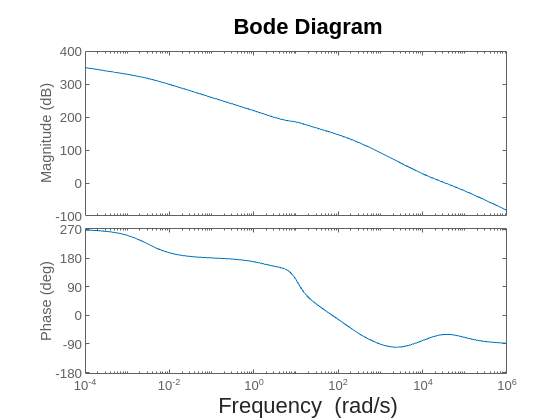


bode(G_tref_w_ol)

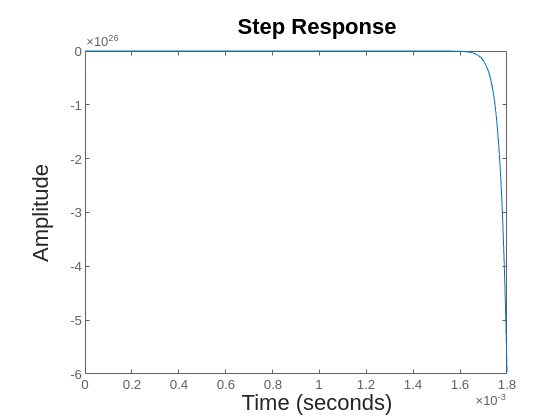

step(G_tref_w_cl)